1.3.2

n = 0:2:60; 
y = sin(n/6); 
subplot(3,1,1) 
stem(n,y,"filled")

n1 = 0:2:60; 
z = sin(n1/6); 
subplot(3,1,2) 
plot(n1,z) 
n2 = 0:10:60; 
w = sin(n2/6); 
subplot(3,1,3) 
plot(n2,w) 

1.3.3

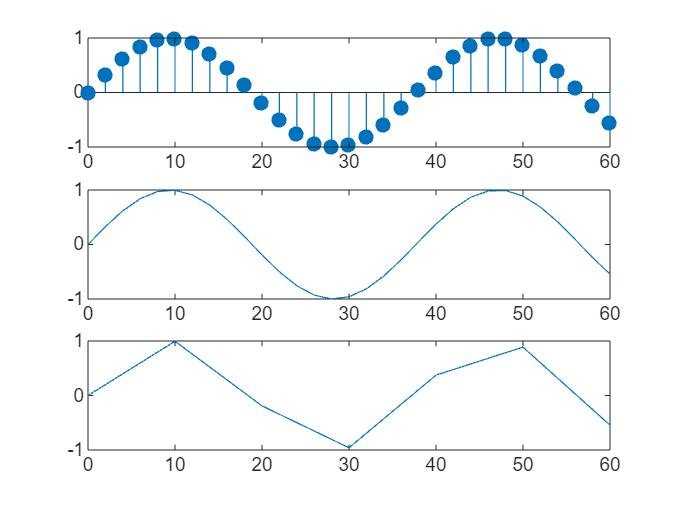

function I = integ1(N)

dt = 2*pi./N;
t = (0:N-1) * dt;
I = dt * sum(sin(5.*t).^2);
end

function J = integ2(N)
dt = 1./N;
t = (0:N-1) * dt;
J = dt * sum(exp(t));
end

N = 1:1:100;
I_result = zeros(size(N));
J_result = zeros(size(N));
for k = 1:length(N)
    I_result(k) = integ1(N(k));
    J_result(k) = integ2(N(k));
end

clf;
figure
subplot(2,1,1);
plot(N,I_result);
subplot(2,1,2);
plot(N,J_result,"r");

1.4

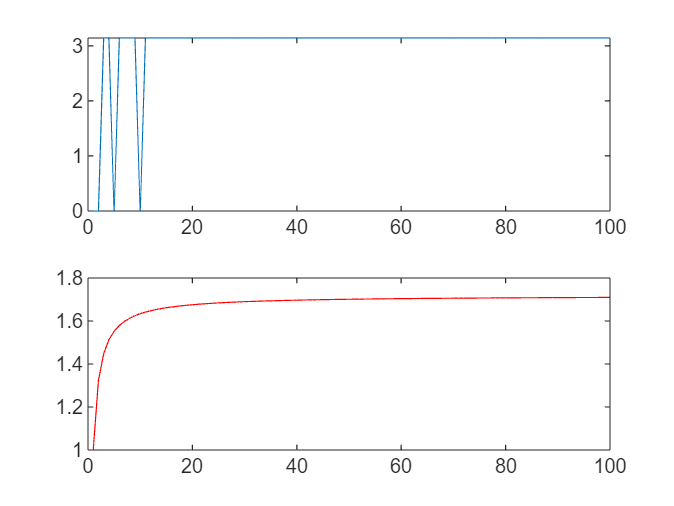

speech = audioread('speech.au');
plot(speech);
sound(speech);

1.5

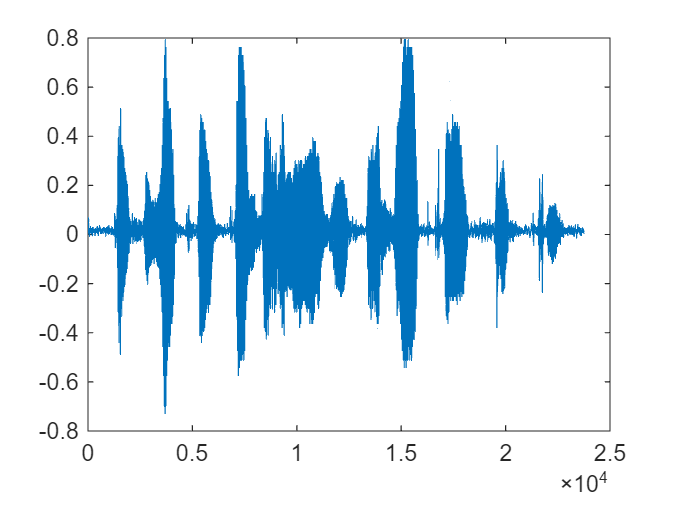

clear;
clc;

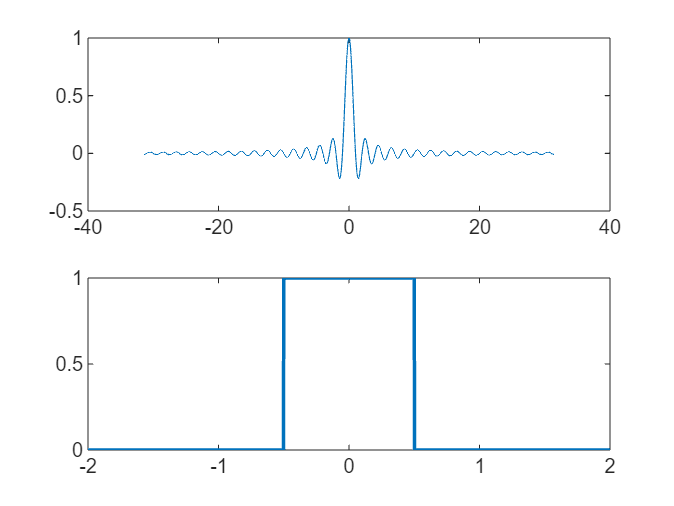

clf;

figure;
t1 = linspace(-10*pi, 10*pi, 4001);
y1 = sinc(t1);
subplot(2,1,1)
plot(t1, y1)

t2 = linspace(-2, 2, 2001);
y2 = (abs(t2)<=0.5);
subplot(2,1,2)
plot(t2,y2, ...
    "LineWidth",1.5)

n1 = -20:20;
u = (n1>=0);
u_10 = (n1>=10);
x = u-u_10;

y1 = zeros(size(n1))
figure
round = 1;
for a = [0.8 1.0 1.5]
    for k = 1:length(n1)
        y1(k) = (a.^n1(k)).*x(k);

y1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


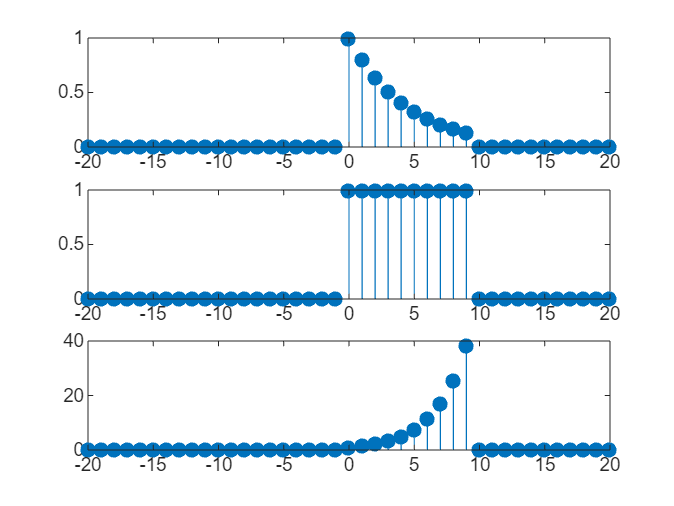

    end
    subplot(3,1,round)
    stem(n1,y1,"filled");
    round = round + 1;
end
